## Data Loaded from experiments:

The data are collected from the digital twin application. The first experiment is running a successful flight mission where the drone fly to 4 waypoints and return to the start position for landing. The data collected from the first experiment are stored in the variable "data_baseline" and are used to calculate probability scores. The second experiment  is a flight mission where the flight mission result in an accident by a simulated intrusion when the drone fails to return and land in the start position. The collected data for the second experiment are stored in the variable "data_realtime".

% Load Data collected during the experiments
data_baseline = load("data\monitored_data_04-Nov-2024 10-33-27.mat").features;
data_realtime = load("data\monitored_data_04-Nov-2024 10-50-58.mat").features;

% Define timesteps
timesteps_baseline = data_baseline(1, :);
timesteps_realtime = data_realtime(1, :);


## Calculation of baseline probability scores:

% Predictions baseline for normal flight scenario
baseline_timeseries = data_baseline(2:19, :);
baseline_timeseries(4, : ) = [];
baseline_timeseries(7, : ) = [];

% Calculate predictions
net = coder.loadDeepLearningNetwork('network.mat')

net =   SeriesNetwork with properties:

         Layers: [9×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'RMSES'}


baseline_predictions = predict(net, baseline_timeseries, "MiniBatchSize", 1)

baseline_predictions = 16×111221 single matrix
    0.0003   -0.0390   -0.0918   -0.1336   -0.1479   -0.1403   -0.1256   -0.1125   -0.1028   -0.0960   -0.0912   -0.0879   -0.0857   -0.0842   -0.0833   -0.0828   -0.0826   -0.0826   -0.0828   -0.0831   -0.0834   -0.0837   -0.0841   -0.0845   -0.0848   -0.0851   -0.0854   -0.0857   -0.0859   -0.0861   -0.0863   -0.0865   -0.0866   -0.0867   -0.0869   -0.0870   -0.0871   -0.0871   -0.0872   -0.0873   -0.0873   -0.0874   -0.0874   -0.0874   -0.0875   -0.0875   -0.0875   -0.0875   -0.0875   -0.0876
   -0.0523   -0.1118   -0.1754   -0.2261   -0.2596   -0.2792   -0.2886   -0.2908   -0.2888   -0.2850   -0.2808   -0.2771   -0.2739   -0.2714   -0.2694   -0.2679   -0.2666   -0.2656   -0.2648   -0.2642   -0.2636   -0.2632   -0.2628   -0.2624   -0.2621   -0.2619   -0.2616   -0.2614   -0.2612   -0.2611   -0.2609   -0.2608   -0.2607   -0.2606   -0.2605   -0.2604   -0.2603   -0.2603   -0.2602   -0.2602   -0.2601   -0.2601   -0.2601   -0.2600   -0.2600  

loss_baseline = mse(baseline_predictions, baseline_timeseries)

loss_baseline = single
0.1782


% Measurements sets for baseline 
trajectory_bl = sqrt(sum((baseline_timeseries(1:3, :) - baseline_predictions(1:3, :)).^2)./3);
waypoints_bl = sqrt(sum((baseline_timeseries(4:6, :) - baseline_predictions(4:6, :)).^2)./3);
gyroscope_bl = sqrt(sum((baseline_timeseries(7:9, :) - baseline_predictions(7:9, :)).^2)./3);
accelerometer_bl = sqrt(sum((baseline_timeseries(10:12, :) - baseline_predictions(10:12, :)).^2)./3);
altittude_bl = sqrt(sum((baseline_timeseries(13:15, :) - baseline_predictions(13:15, :)).^2)./3);
throttle_bl = sqrt((baseline_timeseries(16, :) - baseline_predictions(16, :)).^2);

% Baseline probability districutions
baseline_measurement_sets = {trajectory_bl, waypoints_bl, gyroscope_bl, accelerometer_bl, altittude_bl, throttle_bl}

baseline_measurement_sets = 1×6 cell array
    {[0.0302 0.1041 0.1328 0.1769 0.2106 0.2273 0.2302 0.2251 0.2168 0.2084 0.2010 0.1950 0.1901 0.1862 0.1830 0.1805 0.1785 0.1768 0.1754 0.1743 0.1733 0.1725 0.1718 0.1713 0.1708 0.1704 0.1701 0.1698 0.1695 0.1693 0.1692 0.1690 0.1689 0.1688 0.1687 0.1686 0.1685 0.1685 0.1684 0.1684 0.1683 0.1683 0.1683 0.1683 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1681 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1682 0.1681 0.1681 0.1681

baseline_set = vertcat(baseline_measurement_sets{:})

baseline_set = 6×111221 single matrix
    0.0302    0.1041    0.1328    0.1769    0.2106    0.2273    0.2302    0.2251    0.2168    0.2084    0.2010    0.1950    0.1901    0.1862    0.1830    0.1805    0.1785    0.1768    0.1754    0.1743    0.1733    0.1725    0.1718    0.1713    0.1708    0.1704    0.1701    0.1698    0.1695    0.1693    0.1692    0.1690    0.1689    0.1688    0.1687    0.1686    0.1685    0.1685    0.1684    0.1684    0.1683    0.1683    0.1683    0.1683    0.1682    0.1682    0.1682    0.1682    0.1682    0.1682
    0.0568    0.4440    0.3644    0.3070    0.2758    0.2612    0.2522    0.2438    0.2356    0.2287    0.2233    0.2195    0.2170    0.2155    0.2146    0.2142    0.2141    0.2143    0.2145    0.2148    0.2152    0.2156    0.2159    0.2162    0.2165    0.2168    0.2171    0.2173    0.2175    0.2177    0.2178    0.2179    0.2180    0.2181    0.2182    0.2183    0.2183    0.2184    0.2184    0.2185    0.2185    0.2185    0.2185    0.2186    0.2186    0.2186 

baseline_probabilities =  softmax(baseline_set)

baseline_probabilities = 6×111221 single matrix
    0.0048    0.0088    0.0185    0.0392    0.0683    0.0937    0.1084    0.1148    0.1170    0.1177    0.1176    0.1175    0.1174    0.1173    0.1173    0.1173    0.1173    0.1175    0.1176    0.1177    0.1177    0.1178    0.1179    0.1179    0.1180    0.1182    0.1183    0.1183    0.1183    0.1184    0.1185    0.1185    0.1185    0.1186    0.1186    0.1186    0.1187    0.1187    0.1187    0.1188    0.1188    0.1186    0.1186    0.1187    0.1187    0.1187    0.1186    0.1186    0.1186    0.1186
    0.0050    0.0124    0.0234    0.0447    0.0729    0.0970    0.1108    0.1170    0.1192    0.1201    0.1203    0.1204    0.1206    0.1208    0.1210    0.1213    0.1216    0.1220    0.1223    0.1225    0.1228    0.1230    0.1232    0.1234    0.1235    0.1238    0.1240    0.1241    0.1242    0.1243    0.1244    0.1244    0.1245    0.1246    0.1246    0.1247    0.1247    0.1247    0.1248    0.1249    0.1249    0.1248    0.1248    0.1248    0.1248 

## Calculation of  probability scores from the second experiment data


% Predictions realtime for abnormal flight mission
realtime_timeseries = data_realtime(2:19, :);
realtime_timeseries(4, : ) = [];
realtime_timeseries(7, : ) = [];

% Calculate predictions  
net = coder.loadDeepLearningNetwork('network.mat')

net =   SeriesNetwork with properties:

         Layers: [9×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'RMSES'}


realtime_predictions = predict(net, realtime_timeseries, "MiniBatchSize", 1)

realtime_predictions = 16×95878 single matrix
    0.0003   -0.0391   -0.0918   -0.1336   -0.1478   -0.1403   -0.1256   -0.1124   -0.1027   -0.0959   -0.0912   -0.0878   -0.0856   -0.0841   -0.0832   -0.0827   -0.0825   -0.0826   -0.0827   -0.0830   -0.0833   -0.0837   -0.0840   -0.0844   -0.0847   -0.0850   -0.0853   -0.0856   -0.0858   -0.0861   -0.0863   -0.0864   -0.0866   -0.0867   -0.0868   -0.0869   -0.0870   -0.0871   -0.0872   -0.0872   -0.0873   -0.0873   -0.0874   -0.0874   -0.0875   -0.0875   -0.0875   -0.0875   -0.0875   -0.0876
   -0.0523   -0.1119   -0.1755   -0.2263   -0.2598   -0.2794   -0.2888   -0.2909   -0.2889   -0.2850   -0.2809   -0.2771   -0.2740   -0.2715   -0.2695   -0.2679   -0.2666   -0.2657   -0.2649   -0.2642   -0.2636   -0.2632   -0.2628   -0.2624   -0.2621   -0.2618   -0.2616   -0.2614   -0.2612   -0.2610   -0.2609   -0.2608   -0.2606   -0.2605   -0.2605   -0.2604   -0.2603   -0.2603   -0.2602   -0.2602   -0.2601   -0.2601   -0.2601   -0.2600   -0.2600   

loss_realtime = mse(realtime_predictions, realtime_timeseries)

loss_realtime = single
0.5752


% Measurements sets for realtime
trajectory_rt = sqrt(sum((realtime_timeseries(1:3, :) - realtime_predictions(1:3, :)).^2)./3);
waypoints_rt = sqrt(sum((realtime_timeseries(4:6, :) - realtime_predictions(4:6, :)).^2)./3);
gyroscope_rt = sqrt(sum((realtime_timeseries(7:9, :) - realtime_predictions(7:9, :)).^2)./3);
accelerometer_rt = sqrt(sum((realtime_timeseries(10:12, :) - realtime_predictions(10:12, :)).^2)./3);
altittude_rt = sqrt(sum((realtime_timeseries(13:15, :) - realtime_predictions(13:15, :)).^2)./3);
throttle_rt = sqrt((realtime_timeseries(16, :) - realtime_predictions(16, :)).^2);

% Baseline probability districutions
realtime_measurement_sets = {trajectory_rt, waypoints_rt, gyroscope_rt, accelerometer_rt, altittude_rt, throttle_rt}

realtime_measurement_sets = 1×6 cell array
    {[0.0302 0.0948 0.1235 0.1687 0.2035 0.2211 0.2246 0.2197 0.2116 0.2031 0.1957 0.1895 0.1846 0.1806 0.1774 0.1748 0.1727 0.1709 0.1695 0.1683 0.1673 0.1664 0.1657 0.1651 0.1646 0.1642 0.1638 0.1635 0.1632 0.1630 0.1628 0.1626 0.1625 0.1624 0.1623 0.1622 0.1621 0.1621 0.1620 0.1620 0.1619 0.1619 0.1619 0.1618 0.1618 0.1618 0.1618 0.1618 0.1618 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1618 0.1618 0.1618 0.1618 0.1618 0.1618 0.1618 0.1618 0.1618 0.1618 0.1618 0.1618 0.1618 0.1618 0.1618 0.1618 0.1618 0.1618 0.1618 0.1618 0.1618 0.1618 0.1618 0.1618 0.1618 0.1618 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1617 0.1616

realtime_set = vertcat(realtime_measurement_sets{:})

realtime_set = 6×95878 single matrix
    0.0302    0.0948    0.1235    0.1687    0.2035    0.2211    0.2246    0.2197    0.2116    0.2031    0.1957    0.1895    0.1846    0.1806    0.1774    0.1748    0.1727    0.1709    0.1695    0.1683    0.1673    0.1664    0.1657    0.1651    0.1646    0.1642    0.1638    0.1635    0.1632    0.1630    0.1628    0.1626    0.1625    0.1624    0.1623    0.1622    0.1621    0.1621    0.1620    0.1620    0.1619    0.1619    0.1619    0.1618    0.1618    0.1618    0.1618    0.1618    0.1618    0.1617
    0.0569    0.4440    0.3643    0.3069    0.2758    0.2612    0.2521    0.2437    0.2356    0.2286    0.2233    0.2195    0.2170    0.2154    0.2146    0.2142    0.2141    0.2142    0.2145    0.2148    0.2152    0.2156    0.2159    0.2163    0.2166    0.2168    0.2171    0.2173    0.2175    0.2177    0.2178    0.2180    0.2181    0.2182    0.2182    0.2183    0.2184    0.2184    0.2185    0.2185    0.2185    0.2186    0.2186    0.2186    0.2186    0.2186  

realtime_probabilities =  softmax(realtime_set)

realtime_probabilities = 6×95878 single matrix
    0.0047    0.0088    0.0184    0.0389    0.0680    0.0934    0.1079    0.1142    0.1163    0.1172    0.1171    0.1170    0.1169    0.1168    0.1168    0.1168    0.1171    0.1172    0.1172    0.1173    0.1174    0.1174    0.1175    0.1177    0.1177    0.1178    0.1178    0.1178    0.1179    0.1179    0.1179    0.1179    0.1179    0.1179    0.1179    0.1179    0.1179    0.1179    0.1179    0.1178    0.1178    0.1178    0.1178    0.1178    0.1178    0.1178    0.1178    0.1176    0.1176    0.1176
    0.0049    0.0124    0.0234    0.0447    0.0731    0.0972    0.1109    0.1169    0.1192    0.1202    0.1204    0.1205    0.1207    0.1210    0.1212    0.1215    0.1220    0.1223    0.1226    0.1229    0.1231    0.1234    0.1236    0.1239    0.1240    0.1242    0.1243    0.1243    0.1244    0.1245    0.1246    0.1246    0.1246    0.1247    0.1247    0.1247    0.1247    0.1247    0.1248    0.1247    0.1247    0.1247    0.1247    0.1246    0.1246  

## Figure 4: Prediction scores for trajectory and waypoints

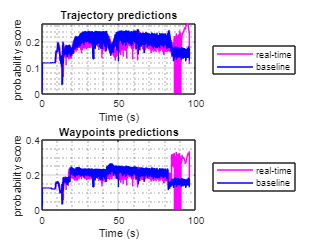

% Prediction scores for trajectory and waypoints
figure;title('trajectories and waypoints reconstruction');
subplot(2,1,1);
    plot(timesteps_realtime, realtime_probabilities(1, :), 'm');
    hold on;
    plot(timesteps_baseline(:,1:95878), baseline_probabilities(1,1:95878), 'b');
    grid on; grid minor; 
    xlabel('Time (s)');ylabel('probability score');title('Trajectory predictions');
    legend('real-time','baseline','Location','eastoutside')
subplot(2,1,2);
    plot(timesteps_realtime, realtime_probabilities(2,:), 'm');
    hold on;
    plot(timesteps_baseline(:,1:95878), baseline_probabilities(2,1:95878), 'b');
    grid on; grid minor; 
    xlabel('Time (s)');ylabel('probability score');title('Waypoints predictions');
    legend('real-time','baseline', 'Location','eastoutside')

## Figure 5: Prediction scores for internal system measurements

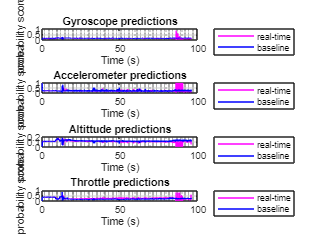

 % Prediction scores for internal system measurements
figure;title('Sensors');
subplot(4,1,1);
    plot(timesteps_realtime, realtime_probabilities(3, :), 'm');
    hold on;
    plot(timesteps_baseline(:,1:95878), baseline_probabilities(3, 1:95878), 'b');
grid on; grid minor; 
xlabel('Time (s)');ylabel('probability score');title('Gyroscope predictions');
legend('real-time','baseline', 'Location','eastoutside')
subplot(4,1,2);
    plot(timesteps_realtime, realtime_probabilities(4, :), 'm');
    hold on;
    plot(timesteps_baseline(:,1:95878), baseline_probabilities(4, 1:95878), 'b');
grid on; grid minor; 
xlabel('Time (s)');ylabel('probability score');title('Accelerometer predictions');
legend('real-time','baseline', 'Location','eastoutside')
subplot(4,1,3);
    plot(timesteps_realtime, realtime_probabilities(5, :), 'm');
    hold on;
    plot(timesteps_baseline(:,1:95878), baseline_probabilities(5, 1:95878), 'b');
grid on; grid minor; 
xlabel('Time (s)');ylabel('probability score');title('Altittude predictions');
legend('real-time','baseline', 'Location','eastoutside')
subplot(4,1,4);
    plot(timesteps_realtime, realtime_probabilities(6, :), 'm');
    hold on;
    plot(timesteps_baseline(:,1:95878), baseline_probabilities(6, 1:95878), 'b');
grid on; grid minor; 
xlabel('Time (s)');ylabel('probability score');title('Throttle predictions');
legend('real-time','baseline', 'Location','eastoutside')

## Figure 6: KL divergence score for the predictions

% KL divergence
baseline = baseline_probabilities(:, 1:95878)

baseline = 6×95878 single matrix
    0.0048    0.0088    0.0185    0.0392    0.0683    0.0937    0.1084    0.1148    0.1170    0.1177    0.1176    0.1175    0.1174    0.1173    0.1173    0.1173    0.1173    0.1175    0.1176    0.1177    0.1177    0.1178    0.1179    0.1179    0.1180    0.1182    0.1183    0.1183    0.1183    0.1184    0.1185    0.1185    0.1185    0.1186    0.1186    0.1186    0.1187    0.1187    0.1187    0.1188    0.1188    0.1186    0.1186    0.1187    0.1187    0.1187    0.1186    0.1186    0.1186    0.1186
    0.0050    0.0124    0.0234    0.0447    0.0729    0.0970    0.1108    0.1170    0.1192    0.1201    0.1203    0.1204    0.1206    0.1208    0.1210    0.1213    0.1216    0.1220    0.1223    0.1225    0.1228    0.1230    0.1232    0.1234    0.1235    0.1238    0.1240    0.1241    0.1242    0.1243    0.1244    0.1244    0.1245    0.1246    0.1246    0.1247    0.1247    0.1247    0.1248    0.1249    0.1249    0.1248    0.1248    0.1248    0.1248    0.1248    0.

KL_divergence = sum(baseline.*log(baseline./realtime_probabilities))

KL_divergence = 1×95878 single row vector
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


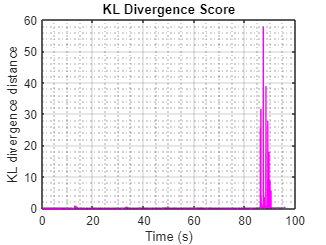

figure;title('KL');
plot(timesteps_realtime, KL_divergence, 'm');
hold on;
grid on; grid minor; 
xlabel('Time (s)');ylabel('KL divergence distance');title('KL Divergence Score');